[X,Y,Z] = cylinder(50,100)

X =    50.0000   49.9013   49.6057   49.1144   48.4292   47.5528   46.4888   45.2414   43.8153   42.2164   40.4508   38.5257   36.4484   34.2274   31.8712   29.3893   26.7913   24.0877   21.2890   18.4062   15.4508   12.4345    9.3691    6.2667    3.1395    0.0000   -3.1395   -6.2667   -9.3691  -12.4345  -15.4508  -18.4062  -21.2890  -24.0877  -26.7913  -29.3893  -31.8712  -34.2274  -36.4484  -38.5257  -40.4508  -42.2164  -43.8153  -45.2414  -46.4888  -47.5528  -48.4292  -49.1144  -49.6057  -49.9013
   50.0000   49.9013   49.6057   49.1144   48.4292   47.5528   46.4888   45.2414   43.8153   42.2164   40.4508   38.5257   36.4484   34.2274   31.8712   29.3893   26.7913   24.0877   21.2890   18.4062   15.4508   12.4345    9.3691    6.2667    3.1395    0.0000   -3.1395   -6.2667   -9.3691  -12.4345  -15.4508  -18.4062  -21.2890  -24.0877  -26.7913  -29.3893  -31.8712  -34.2274  -36.4484  -38.5257  -40.4508  -42.2164  -43.8153  -45.2414  -46.4888  -47.5528  -48.4292  -49.1144  -49.6057  -49

Y =          0    3.1395    6.2667    9.3691   12.4345   15.4508   18.4062   21.2890   24.0877   26.7913   29.3893   31.8712   34.2274   36.4484   38.5257   40.4508   42.2164   43.8153   45.2414   46.4888   47.5528   48.4292   49.1144   49.6057   49.9013   50.0000   49.9013   49.6057   49.1144   48.4292   47.5528   46.4888   45.2414   43.8153   42.2164   40.4508   38.5257   36.4484   34.2274   31.8712   29.3893   26.7913   24.0877   21.2890   18.4062   15.4508   12.4345    9.3691    6.2667    3.1395
         0    3.1395    6.2667    9.3691   12.4345   15.4508   18.4062   21.2890   24.0877   26.7913   29.3893   31.8712   34.2274   36.4484   38.5257   40.4508   42.2164   43.8153   45.2414   46.4888   47.5528   48.4292   49.1144   49.6057   49.9013   50.0000   49.9013   49.6057   49.1144   48.4292   47.5528   46.4888   45.2414   43.8153   42.2164   40.4508   38.5257   36.4484   34.2274   31.8712   29.3893   26.7913   24.0877   21.2890   18.4062   15.4508   12.4345    9.3691    6.2667    3

Z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


s = surf(Z*50,Y,X)

s =   Surface - 属性:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [2×101 double]
           YData: [2×101 double]
           ZData: [2×101 double]
           CData: [2×101 double]

  显示 所有属性


s.EdgeColor = 'none'

s =   Surface - 属性:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [2×101 double]
           YData: [2×101 double]
           ZData: [2×101 double]
           CData: [2×101 double]

  显示 所有属性


hold on


t = linspace(0,1,100)

t =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


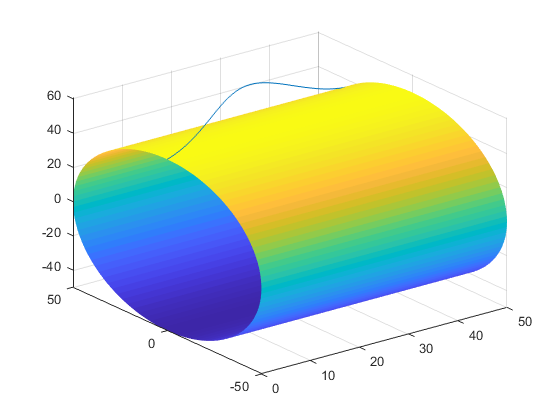

    x = 50;  %三轴放大系数
    y = 5;
    z = 7.5;
    funr = 50 + z * ( 1 + cos( -pi + 2*pi*t) ) ;
    twist = pi/2 - pi * t / 4 ; % 扭转15°
    
    linex = x * t ;
    liney = funr .* cos( twist ) ;
    linez = funr .* sin( twist ) ;

lot3(linex,liney,linez)